# TFM SCRIPT 2

## Theodorsen's Theory

In this first section of the unsteady aerodynamics chapter, some of the basic concepts of the Theodorsen's theory are to be reviewed. 

This theory is essential for almost every classical flutter analysis method, as it allows to express analytically the unsteady aerodynamic forces in the frequency domain. One of the drawbacks of this theory, is that it is only valid for and airfoil whose degree's of freedom are oscillating harmonically. This means that the theory by itself, is not able to estimate the unsteady aerodynamic loads generated by an airfoil exhibiting arbitrary motion.

Regarding flutter analysis methods, the direct consequence is that any method which make use of Theodorsen's theory to predict the unsteady aerodynamic forces, is only fully reliable at the flutter point, where harmonic oscillations of the critical aeroelastic mode take place. Away from the flutter point, the degrees of freedom do not follow harmonic oscillations, and therefore Theodorsen's theory does not estimate the unsteady loads accurately.

Other disadvantage of Theodorsen's theory is that as it was previously mentioned, it estimates the aerodynamic loads in the frequency domain. The non circulatory contribution can be easily transported to the time domain by applying the inverse Fourier transform, as it will be shown lately. However, the circulatory term of the lift presents more difficulties when trying to compute it in the time domain, as the inverse Fourier transform of the Theodorsen's function is not an trivial integral transformation. Moreover, it must be taken into account that this theory applies only to 2D, incompressible and inviscid flows. 

Before stating the unsteady aerodynamic forces expressions, some aspects related to the notation and the geometrical characterization of the airfoil need to be mentioned. 

The airfoil has a chord of value $c$, and semi-chord $c=\frac{b}{2}$. The parameter $a$ is a non dimensional parameter that denotes the distance between the geometrical center of the airfoil ($x=b$) and the elastic axis, or point at where the airfoil rotates about $x_{\textrm{EA}}$. Thus $x_{EA}-b = ab$. Note that if the airfoil rotates about its leading edge, $a=-1$, and if it rotates about the trailing edge $a=1$. 

The system considered has 2 degrees of freedom. The vertical motion of the airfoil, which simulates the bending of a 3D finite wing: commonly called plunge in the literature (denoted as $h$), and the twist angle of the airfoil, which simulates the torsion of a 3D finite wing: commonly called pitch in the literature (denoted as $\alpha$).

The aerodynamic loads are non-dimensionalize with the semichord and the dynamic pressure of the freestream $q_\infty = \frac{1}{2}\rho_\infty U_\infty^2$. Note that the notation $\dot h$ and $\ddot h$ is to say $\frac{dh}{dt}$ and $\frac{d^2h}{dt^2}$ respectively.

Hence, the unsteady aerodynamic forces given by Theodorsen's theory are:


$$
    \frac{{Q}_h(k)}{q_\infty b} = -2\pi\left[\frac{b}{U_\infty}\dot{\alpha} + \left(\frac{b}{U_\infty}\right)^2\left(\frac{\ddot{h}}{b} - a\ddot\alpha\right)\right]-4\pi C(k)\left\{\alpha+\frac{b}{U_\infty}\left[\frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right]\right\},
$$



$$\frac{{Q}_\alpha(k)}{q_\infty b^2} = -2\pi\left\{\frac{b}{U_\infty}\left(\frac{1}{2}-a\right)\dot{\alpha} + \left(\frac{b}{U_\infty}\right)^2\left[-a\frac{\ddot{h}}{b} + \left(\frac{1}{8}+a^2\right)\ddot\alpha\right]\right\} + 4\pi \left(\frac{1}{2}+a\right) C(k)\left\{\alpha+\frac{b}{U_\infty}\left[\frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right]\right\},$$


where$C\left(k\right)$ is the Theodorsen's function. This function is the most important mathematical tool that this theory provides, as it models the phase lag between the airfoil motion and the aerodynamic forces generated, as well as the attenuation of these forces due to the wake effect. The reason why this function is a complex number in the frequency domain, is precisely to take into account the fact that the unsteady aerodynamic loads are lagged with respect to the airfoil's motion.

The function is expressed using Hankel functions of the second kind $H_n^{(2)}$:


$$C(k) = \frac{H_1^{(2)}(k)}{H_1^{(2)}(k) + i H_0^{(2)}(k)}$$


where $k = \frac{\omega b}{U_\infty}$ is the reduced frequency, and $H_n^{(2)}(k) = J_n(k) - i Y_n(k)$, involving Bessel functions of the first $J_n$ and second kind $Y_n$.

The first terms of both equations are called non circulatory or added mass terms, as they are not directly related to the bound vorticity or the wake vorticity of the airfoil. These added mass terms are generated due to the accelerated motion of the airfoil, which accelerates the surrounding air due to its own motion, and therefore, a resulting force is produced. 

It is worthy to note that the main difference between the added mass terms and the circulatory terms is that the second ones are multiplied by the Theodorsen's function $C(k)$ while the first are not. This implies that the added mass terms are in phase with the motion of the airfoil, and consequently the non circulatory part of the lift and moment is generated instantaneously (there is no lag between cause and effect). 

The physical explanation to this fact, is that this theory is formulated for incompressible flows, where and infinite speed of sound is assumed. This means that small pressure perturbations of the flow, propagate instantaneously and therefore, no lag between cause (airfoil motion) and effect (aerodynamic force) exists. 

As for the circulatory part, the two effects mentioned previously that are a direct consequence of Theodorsen's function are the lift attenuation and the phase lag between motion and lift (same for aerodynamic moment). The key is to understand the wake effect on the aerodynamic loads. Since the airfoil is continuously changing its angle of attack and its vertical speed, the circulation around the airfoil (bound vorticity) must change accordingly, in order to fulfill the Kutta condition at the trailing edge. Mathematically, this means that $\Delta C_p(x = 2b) = 0$. 

It is known that for inviscid flows, the Kelvin's theorem states that the global circulation of the fluid must stay constant. Hence, a shedding vortex wake is needed to compensate for the changes in bound circulation. Let say that between two instants in time separated by $\Delta t$, the bound circulation of the airfoil has changed a value $\Delta\Gamma$ to ensure the Kutta condition in both instants. Thus, a vortex with vorticity $-\Delta\Gamma$, must been shed to the wake in order to comply with Kelvin's theorem.

As the shed vortex has opposite sign, it induces a velocity field on the airfoil that opposes the one generated by the bound vorticity. This is the reason why it exists an attenuation of the aerodynamic loads with respect to those estimated by the steady theory. Mathematically, this is clearly seen by analyzing Theodorsen's function: $|C(k)|\leq1 \hspace{1mm}$. 

It is also interesting to observe that $C(k)\rightarrow{}0.5$ as $k\rightarrow{}\infty$. This can be understood thinking that for infinite reduced frequency, the wake vortex is infinitely close to the trailing edge the instant after it has been shed, as the characteristic time of the free wake is infinitely larger than the airfoil's oscillating time. Thus, the influence of this vortex is maximized, and therefore, the attenuation of the circulatory lift is also maximized. This effect is strongly connected to Wagner's function, which will be explained in next sections. This function can be understood as the time domain analogous function of the Theodorsen's function. It can be shown that Wagner's function presents a value of 0.5 when time equals zero.

Regarding the phase lag between the airfoil and the unsteady aerodynamic loads, a new aspect of Theodorsen's theory needs to be taken into account. This is that the shed vortices are dragged downstream with the wake with the same speed than the freestream $U_\infty$. Hence, the effect of a wake vortex which has been shed at an instant $t = t_0$ will loose influence on the circulatory force, as in and instant $t = t_0 + \Delta t$ will be located at a distance from the trailing edge $\Delta x = U_\infty\Delta t$, thus inducing a much weak velocity field on the airfoil. The time difference between the instant the wake vortex $-\Delta \Gamma$ is shed, and the instant at which it is far enough downstream to not practically modify the circulatory lift, is what we call the time lag between cause and effect (motion and aerodynamic load). 

Once all these fundamental concepts regarding Theodorsen's theory have been reviewed, the next step is to compute the aerodynamic forces in the frequency domain, as they are going to be used this way during the next chapters for some of the flutter analysis methods.

As it was explained previously, only apply to harmonic airfoil's motion. Therefore, the degrees of freedom can be assumed to present the following expressions:

$h(t) = \Re\left\{\bar h e^{i\omega t}\right\}$ and $\alpha(t) = \Re\left\{\bar \alpha e^{i\omega t}\right\}$

where $h$ and $\alpha$ can be complex numbers, to account for the possible phase lag between the two degrees of freedom. Note that $\omega$ is the frequency of oscillation of the airfoil. This phase lag between plunge and pitch, will be studied in detail in next sections, as its can be shown that it influence on the complete aeroelastic system stability is large. 

If expressions the harmonic relations of the degrees of freedom are introduced in equations Theodorsen's equations, the complex amplitudes of unsteady aerodynamic forces can be obtained purely in the frequency domain as:


$$\frac{\tilde{Q}_h(k)}{q_\infty b} = -2\pi\left(ik\bar{\alpha} + -k^2\frac{\bar{h}}{b} + ak^2\bar\alpha\right)-4\pi C(k)\left[\bar\alpha+ik\frac{\bar{h}}{b}+\left(\frac{1}{2}-a\right)ik\bar{\alpha}\right]\$$



$$\frac{\tilde{Q}_\alpha(k)}{q_\infty b^2} = -2\pi\left[\left(\frac{1}{2}-a\right)ik\bar{\alpha} + ak^2\frac{\bar{h}}{b} -k^2\left(\frac{1}{8}+a^2\right)\bar\alpha\right] + 4\pi \left(\frac{1}{2}+a\right) C(k)\left[\bar\alpha+ik\frac{\bar{h}}{b}+\left(\frac{1}{2}-a\right)ik\bar{\alpha}\right]$$


These non dimensional complex amplitudes of the unsteady aerodynamic forces in the frequency domain, are function exclusively of the reduced frequency of the oscillations $k$, and the position of the elastic axis $a$.

In order to compute these forces in the time domain, the complex exponential term can be used, as the motion is harmonic. This leads to:


$$Q_h(t) = \Re\left\{\tilde{Q}_h(k)e^{ik\tau}\right\}$$



$$Q_\alpha(t) = \Re\left\{\tilde{Q}_\alpha(k)e^{ik\tau}\right\}$$


Note that $k\tau = \omega t$, as $\tau = \frac{t U_\infty}{b}$ is de non dimensional time: $k\tau = \frac{\omega b}{U_\infty}\cdot\frac{tU_\infty}{b} = \omega t$.

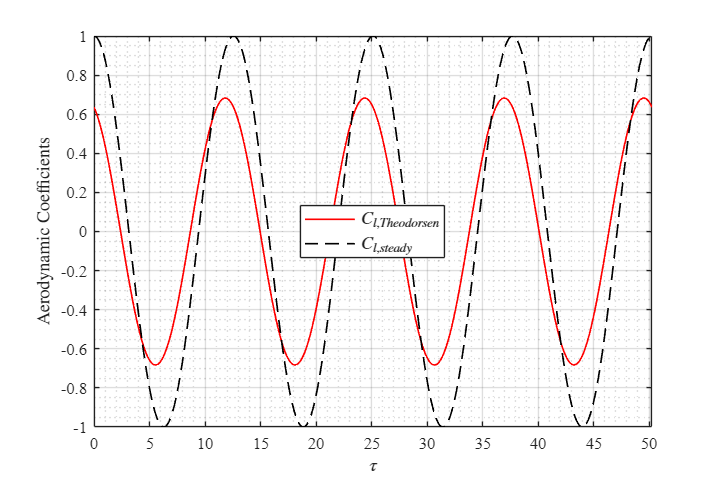

%% Unsteady Aerodynamic Forces Analysis

close all;
clc;
clear all;

%% Parameters

a = 0; % Non dimensional distance between the rotation axis (Elastic Axis) and the geometrical center (x = 0). a = 0 in Patil's (EA at 50% chord)
alpha = 1; % Amplitude of AoA perturbation. 1 rad in Patil's, 1 deg in Simpson's
h = 0; % Amplitude of plunge perturbation. 1 in Patil's, 1 in Simpson's. Is non dimensionalized with the semichord b, (h/b).
k = 0.5; % Reduced frequency. Here is a parameter, in flutter solvers it's part of the solution itself. k = 0.5 for Patil's paper validation
C = Theodorsen_function(k); % Calls Theodorsen's function, and introduces the value of k (reduced freq.)
LAG = deg2rad(0); % Phase lag between the pitch motion and the plunge motion.

%% Pitch and plunge motion of the airfoil

n = 4; % Number of cycles to plot the response
tau_lim = 2*pi/k*n;
tau = linspace(0, tau_lim, 1000); % Time array 

% --- Motion Definition (Analytical) ---
% Position
alpha_t = real(alpha * exp(1i*k*tau)); 
h_t     = real(h * exp(1i*k*tau - 1i*LAG));

% Velocity (First derivative wrt tau)
% d/dtau (e^iktau) = ik * e^iktau
alpha_dot_t = real(1i*k * alpha * exp(1i*k*tau));
h_dot_t     = real(1i*k * h * exp(1i*k*tau - 1i*LAG));

% Acceleration (Second derivative wrt tau)
% d2/dtau2 = (ik)^2 = -k^2
alpha_ddot_t = real(-k^2 * alpha * exp(1i*k*tau));
h_ddot_t     = real(-k^2 * h * exp(1i*k*tau - 1i*LAG));

%% Complex Unsteady Lift and Moment from Theodorsen's Model

C_aero = Unsteady_aero(k,a);
C_l_unsteady = -1*(C_aero(1,1)*h + C_aero(1,2)*alpha);
C_m_unsteady = C_aero(2,1)*h + C_aero(2,2)*alpha;

% Time Domain

for i = 1:1000
    Cl_unsteady_t(i) = real(-1*(C_aero(1,1)*h*exp(1i*k*tau(i) - 1i*LAG) + C_aero(1,2)*alpha*exp(1i*k*tau(i)))); % Change to Imag for alpha * sin(ks) definition as in Simpson's
end

for i = 1:1000
    Cm_unsteady_t(i) = real(C_aero(2,1)*h*exp(1i*k*tau(i) - 1i*LAG) + C_aero(2,2)*alpha*exp(1i*k*tau(i))); % Change to Imag for alpha * sin(ks) definition as in Simpson's
end

%% Complex Steady Lift Amplitude (assuming instantaneous response, and no trailing edge unsteady vortex shedding)

C_l_steady = 4*pi*1;
C_m_steady = 4*pi*1*(0.5+a);

for i = 1:1000
    Cl_steady_t(i) = real(C_l_steady*exp(1i*k*tau(i))); % Change to Imag for alpha * sin(ks) definition as in Simpson's
end

for i = 1:1000
    Cm_steady_t(i) = real(C_m_steady*exp(1i*k*tau(i))); % Change to Imag for alpha * sin(ks) definition as in Simpson's
end

%% Unsteady Aerodynamic functions

function Q_aero = Unsteady_aero(k,a)
    
    C = Theodorsen_function(k);
    Q_aero = zeros(2,2);
    Q_aero(1,1) = -2*pi*(-k^2 + 2*1i*k*C);
    Q_aero(1,2) = -2*pi*(a*k^2 + 1i*k + 2*C*(1 + (0.5-a)*1i*k));
    Q_aero(2,1) = 2*pi*(-a*k^2 + 2*1i*k*C*(0.5+a));
    Q_aero(2,2)= 2*pi*(-1i*k*(0.5-a) + k^2*(1/8+a^2) + 2*C*(0.5+a)*(1 + (0.5-a)*1i*k));

end

function C = Theodorsen_function(k)
    
    C = besselh(1,2,k)/(besselh(1,2,k) + 1i*besselh(0,2,k));

end

figure(1)

plot(tau, Cl_unsteady_t/C_l_steady,'r','LineWidth',1);
hold on 
plot(tau, Cl_steady_t/C_l_steady,'black--','LineWidth',1);
hold on 
legend('$C_{l,Theodorsen}$', '$C_{l,steady}$','Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')
set(gcf, 'Renderer', 'painters');

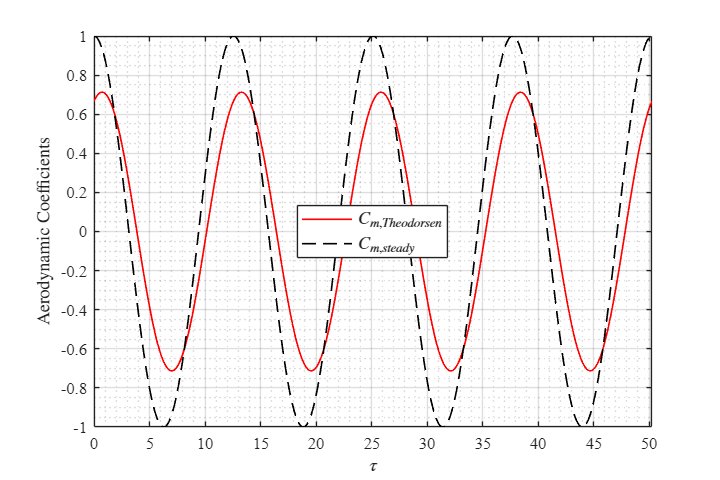


figure(2)

plot(tau, Cm_unsteady_t/C_m_steady,'r','LineWidth',1);
hold on 
plot(tau, Cm_steady_t/C_m_steady,'black--','LineWidth',1);
hold on 
legend('$C_{m,Theodorsen}$','$C_{m,steady}$','Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')
set(gcf, 'Renderer', 'painters');

## Garrick's Theory

This section aims to obtain an expression for the unsteady aerodynamic drag, that was computed by Garrick in 1938. The expression is the following:


$$d = \alpha l - \pi\rho_\infty S^2, $$


where the first term appears due to the projection of the lift in the horizontal plane, while the second term is due to the leading edge suction. Both terms are also present in the steady thin airfoil theory, but they cancel out. This is the reason why the pressure drag of an airfoil in a steady, incompressible and inviscid flow is zero (if boundary layer effects are neglected). 

However, in the unsteady aerodynamic theory, these two contributions can have different complex phase, and therefore, the sum of both contributions at each time instant can be different from zero. 

It is important to point out that all the values that appear in the unsteady drag equation are real. It is a common practice in unsteady aerodynamics to express forces directly in the complex plane (frequency domain). Thus, it is important to remark the following considerations:

$\alpha l = \Re\left\{\alpha\right\}\cdot \Re\left\{l\right\} \neq \Re\left\{\alpha l\right\},$ and $S^2 = \Re\left\{S\right\}\cdot \Re\left\{S\right\} \neq \Re\left\{S^2\right\}.$

Therefore, if complex exponential notation is to be used in order to compute the unsteady drag in the frequency domain, the path would be to compute $l$ and $S$ independently, and then transform this complex expressions to the time domain (real parts).

The leading edge suction term is expressed as:


$$S = \sqrt{\frac{b}{2}}\left[2C(k)\left(U_\infty \alpha + \dot h + b\left(\frac{1}{2} -a\right)\dot \alpha\right) - b\dot \alpha\right]$$


Following the same non dimensionalizing process as for the lift force and applying the previously introduced non dimensional time (and the change of notation for the non dimensional time derivatives), the expression obtained for the unsteady drag coefficient is:


$$C_d = \frac{d}{q_\infty b} =  \alpha C_l -  C_s$$


where $C_l$ is the lift coefficient defined previously and $C_s
$ is the leading edge suction coefficient:


$$C_s = \frac{\pi \rho_\infty S^2}{q_\infty b} = \pi\left\{2C(k)\left[\alpha + \frac{\dot h}{b} + \left(\frac{1}{2} -a\right)\dot \alpha\right] - \dot \alpha\right\}^2$$


Hence, the complete expression for the non dimensional unsteady drag reads as:


$$C_d =  \alpha\left\{2\pi\left(\dot{\alpha} +\frac{\ddot{h}}{b} - a\ddot\alpha\right) + 4\pi C(k) \left[\alpha+\frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right]\right\} - \pi\left\{2C(k)\left[\alpha + \frac{\dot h}{b} + \left(\frac{1}{2} -a\right)\dot \alpha\right] - \dot \alpha\right\}^2$$


Note the non linear behavior of this last expression. The non linearity of the first term is produced by the multiplication of the lift force by the angle of attack, while the second case term is also non linear as it is squared.

It is an error to calculate the this complete $C_d$ expression in the complex domain and then keeping only the real part. As it was explained earlier, the terms of Garrick's expression for the drag are real. Therefore, the path to compute the unsteady drag would be to determine first the real expressions of $C_l$, $C_s$ and $\alpha$, and then, multiply them to obtain the total unsteady drag. 

Hence, applying the same assumptions than in Theodorsen's theory (degrees of freedom $h$ and $\alpha
$ oscillating harmonically) and using complex exponential to write down the forces in the frequency domain, we have that:


$$S = \sqrt{\frac{b}{2}}\left[2C(k)\left(U_\infty \bar \alpha + i\omega \bar h+  i\omega b\left(\frac{1}{2} -a\right)\bar\alpha\right) - i\omega b\bar\alpha\right] \cdot e^{i\omega t}$$


Hence, the leading edge suction coefficient becomes:


$$C_s = \pi \cdot \left(\Re\left\{\left[2 C(k)\left(\bar \alpha + ik\frac{\bar h}{b} + \left(\frac{1}{2}-a\right)ik\bar \alpha \right) - ik\alpha\right]e^{ik\tau}\right\} \right)^2$$


The complete unsteady drag coefficient can be therefore determined if the first term (lift contribution) is also taken into account:


$$C_d = \underbrace{\Re\left\{2\pi\left(ik\bar{\alpha} -k^2\frac{\bar{h}}{b} + ak^2\bar\alpha\right) e^{ik\tau} + 4\pi C(k)\left[\bar\alpha+ik\frac{\bar{h}}{b}+\left(\frac{1}{2}-a\right)ik\bar{\alpha}\right] e^{ik\tau}\right\} \cdot \Re \left\{\bar \alpha e^{ik\tau}\right\}}_{\alpha C_l} - \underbrace{\pi\cdot  \left(\Re\left\{\left[2C(k)\left(\bar \alpha + ik\frac{\bar h}{b} + \left(\frac{1}{2}-a\right)ik\bar \alpha \right)-i k \bar \alpha\right]e^{ik\tau}\right\} \right)^2}_{C_s}$$


It is clear that the nonlinearities of this aerodynamic force, introduce two main mathematical problems if one wants to couple the force to the aeroelastic system. The first problem is that both degrees of freedom are squared, thus, the classical methods in which linear algebra is used to solve the eigenvalues and eigenvector of the complete aeroelastic matrix of the system, is no long a possibility. Secondly, methods that work directly in the frequency domain (as k method), cannot deal with forces which occur at different frequencies than the flutter frequency. The problem of this force is that it acts at twice the frequency of oscillation of the system and the lift and moment forces. 

Therefore, a new method needs to be considered in order to couple this highly non linear drag force into the aeroelastic equations of the system.

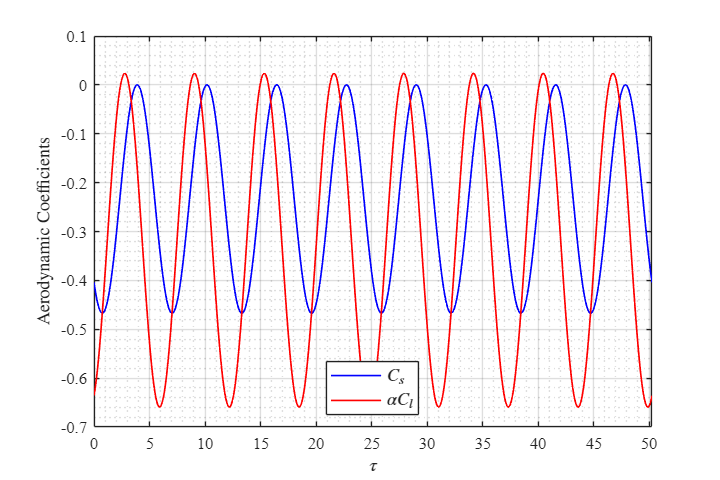

%% Complex Unsteady Drag from Garrick's model

for i = 1:1000
    Cd_Lift_t(i) = real(alpha*exp(1i*k*tau(i)))*real(Cl_unsteady_t(i)); % Change to Imag for alpha * sin(ks) definition as in Simpson's
    Cd_LES_t(i) = -pi*(real(2*C*(alpha*exp(1i*k*tau(i)) + 1i*k*h*exp(1i*k*tau(i) + - 1i*LAG) + 1i*k*(0.5-a)*alpha*exp(1i*k*tau(i)))-1i*k*alpha*exp(1i*k*tau(i))))^2; % (real S)^2 instead of (real(S))^2 --> Garrick's
    Cd_t(i) = Cd_Lift_t(i) + Cd_LES_t(i);
end

figure(3)

plot(tau, Cd_LES_t/C_l_steady,'b','LineWidth',1);
hold on
plot(tau, -Cd_Lift_t/C_l_steady,'r','LineWidth',1);
legend('$C_{s}$', '$\alpha C_{l}$', 'Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')
set(gcf, 'Renderer', 'painters');

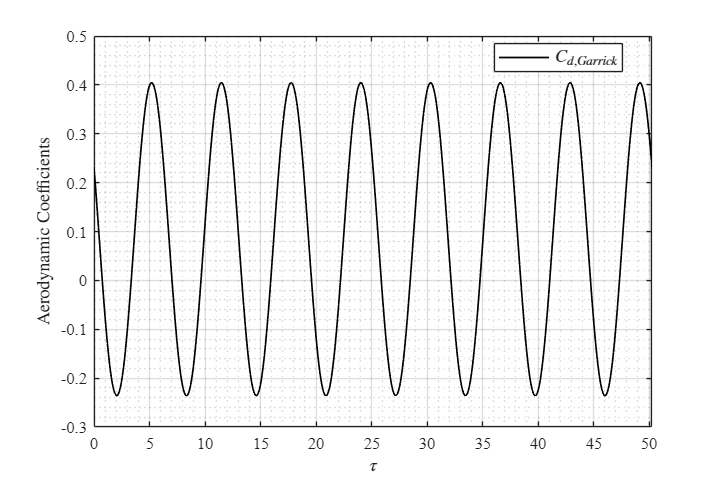


figure()

plot(tau, Cd_t/C_l_steady,'black','LineWidth',1);
legend('$C_{d,Garrick}$', 'Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')
set(gcf, 'Renderer', 'painters');

## Wagner Function and Jones Approximation

Once Theodorsen's and Garrick's work has been revisited, it has been proven that this unsteady aerodynamic theory is limited to airfoil's oscillating harmonically in time. Thus, when applied to the complete aeroelastic problem, it only predicts the aerodynamic forces at exactly the flutter point. If the complete time domain evolution of the system is to be modeled, starting at the initial perturbation and ending at the divergence or damping of this perturbation, Theodorsen's and Garrick's theories are no longer an option.

Hence, a new formulation of the unsteady loads needs to be arranged, in order to capture the full time evolution of an arbitrary airfoil's motion. 

For that purpose, the first tool that one can think of, is the Wagner's indicial function. This function acts as a time domain analogous of the Theodorsen's function. It was originally identified by Wagner in 1925, and it allows the computation of the unsteady aerodynamic response due to a sudden change in the angle of attack. It was formulated by Wagner as:


$$    \Phi(t) = \frac{2}{\pi}\int_0^\infty{\frac{F(k)}{k}\sin{\left(kt\right)}}\mathrm{d}k,$$


where $k$ is the reduced frequency, and $F\left(k\right)$ is the real part of Theodorsen's function (i.e. $F(k) = \Re\left\{C(k)\right\}$). 

Before continuing, a slight change in notation is going to be included, in order to match the typical notation used in time domain calculations. This change implies defining a new variable called non dimensional time and defined as $\tau =\frac{U_{\infty } }{b}t$. Therefore, the time derivatives need to be modified accordingly such that $\frac{d\xi}{dt} = \frac{U_\infty}{b}\frac{d\xi}{d\tau} $ and $\frac{d^2\xi}{dt^2} = \left(\frac{U_\infty}{b}\right)^2\frac{d^2\xi}{d\tau^2} $, being $\xi$ an arbitrary degree of freedom of the system. To simplify the notation, the new change is that $\dot\xi = \frac{d\xi}{d\tau} $ and $\ddot\xi = \frac{d^2\xi}{d\tau^2} $ instead of the previous one used ($\dot\xi = \frac{d\xi}{dt} $ and $\ddot\xi = \frac{d^2\xi}{dt^2} $). 

Introducing this new notation with respect to the non dimensional time, the equations for the non dimensional unsteady forces for harmonic motion from Theodorsen's theory can be expressed as follows:


$$\frac{{Q}_h(k)}{q_\infty b} = -2\pi\left(\dot{\alpha} +\frac{\ddot{h}}{b} - a\ddot\alpha\right) - 4\pi C(k) \left[\alpha+\frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right]$$



$$\frac{{Q}_\alpha(k)}{q_\infty b^2} = -2\pi\left[\left(\frac{1}{2}-a\right)\dot{\alpha} + a\frac{\ddot{h}}{b} + \left(\frac{1}{8}+a^2\right)\ddot\alpha\right] + 4\pi \left(\frac{1}{2}+a\right) C(k)\left[\alpha+ \frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right]$$


This way of presenting the aerodynamic loads is typical in flutter analysis, but if we want to refer these loads to the typical lift and moment coefficients, we should need to take into account that $C_l (k)= -\frac{Q_h(k)}{q_\infty b}$ (negative as $h
$ is defined positive for negative $z$ coordinate) and $C_m (k)= \frac{Q_\alpha(k)}{q_\infty b^2}$. It is important to note that the forces are non dimensionalize with the semi-chord, therefore the slope of the lift curve for the quasi-steady approximation is $C_{l_\alpha} = 4\pi$. This can be checked by setting the reduced frequency $k = 0$ in the unsteady lift equation, which leads to obtaining $C_l = 4\pi C(0)\alpha = 4\pi \alpha$. 

Regarding the unsteady drag and given the Garrick's formula:


$$d = \alpha l-\pi\rho_\infty S^2$$


where the first term appears due to the projection of the lift in the horizontal plane, while the second term is due to the leading edge suction. Both terms are also present in the steady thin airfoil theory, but they cancel out. This is the reason why the pressure drag of an airfoil in a steady, incompressible and inviscid flow is zero (if boundary layer effects are neglected).

Recovering the complete equation of the unsteady drag coefficient we have:


$$C_d =  \alpha\left\{2\pi\left(\dot{\alpha} +\frac{\ddot{h}}{b} - a\ddot\alpha\right) + 4\pi C(k) \left[\alpha+\frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right]\right\} - \pi\left\{2C(k)\left[\alpha + \frac{\dot h}{b} + \left(\frac{1}{2} -a\right)\dot \alpha\right] - \dot \alpha\right\}^2$$


With this last expression, the three unsteady aerodynamic forces are known: $C_l$, $C_d$ and $C_m$. However, the Theodorsen's function $C\left(k\right)$ is a complex number, defined in the complex frequency domain. This is the main reason why these expressions are only valid for pure harmonic motion of the airfoil.

In order to extend these equation for arbitrary motion of an airfoil, Wagner's function is introduced, as an analogous of the Theodorsen's function but in the time domain instead. Both function's core is the same: Taking into account the time lag between the airfoil motion and the produced aerodynamic forces, as well as the attenuation of this forces induced by the effect of the shedding vortices at the wake. 

The first thing to consider when trying to compute the aerodynamic loads in the time domain, is to differentiate between the circulatory and the non circulatory parts of each load. The circulatory parts are multiplied by Theodorsen's function, which is defined in the complex frequency domain and therefore, they will need a special treatment if one wants to compute them in the time domain. 

However, the non circulatory parts can be directly computed in the time domain if the degrees of freedom as well as their derivatives with respect to non dimensional time are known. Thus, there is no need to use Wagner's function to lead with this non circulatory contributions, which are defined as (from previous complete expressions, but only keeping the added mass terms):


$$\frac{Q^{NC}_h(\tau)}{q_\infty b} = -C_l^{NC} (\tau)= -2\pi\left(\dot{\alpha} +\frac{\ddot{h}}{b} - a\ddot\alpha\right)$$



$$\frac{Q^{NC}_\alpha(\tau)}{q_\infty b^2} = C_m^{NC} (\tau)= -2\pi\left[\left(\frac{1}{2}-a\right)\dot{\alpha} + a\frac{\ddot{h}}{b} + \left(\frac{1}{8}+a^2\right)\ddot\alpha\right] $$



$$C^{NC}_d(\tau) =  2\pi\alpha\left(\dot{\alpha} +\frac{\ddot{h}}{b} - a\ddot\alpha\right) - \pi\dot\alpha^2$$


These expressions are fully defined in the time domain and they are valid for arbitrary airfoil motion. 

On the other hand, the circulatory contributions need to be rearranged. Before do so, it is important to see that in all the expressions, the Theodorsen's function is always multiplying the term: $U_\infty\alpha + \frac{\dot h}{b} + b \left(\frac{1}{2} -a\right)\dot \alpha$. This term, can be geometrically interpreted as the downwash velocity at the point 3/4 of the chord, considering also the velocities induced by the vertical plunge and the pitch motion of the airfoil. Is common in the literature to express it as:


$$w_{3/4} = U_\infty\alpha + \dot h + b \left(\frac{1}{2} -a\right)\dot \alpha$$


As we were working with non dimensional velocities and non dimensional time, the non dimensional form of this velocity is:


$$\hat w_{3/4} = \alpha + \frac{\dot h}{b} +  \left(\frac{1}{2} -a\right)\dot \alpha$$


Hence, the expressions for the circulatory parts of the unsteady aerodynamic loads become:


$$\frac{Q^C_h(k)}{q_\infty b} = -C_l^C(k) =   - 4\pi C(k)\hat w_{3/4}$$



$$\frac{Q^C_\alpha(k)}{q_\infty b} = C_m^C(k) =   4\pi \left(\frac{1}{2}+a\right)  C(k)\hat w_{3/4}$$



$$C_d^C(k) = 4\pi C(k)\hat w_{3/4}\left[\alpha - C(k)\hat w_{3/4} + \dot \alpha \right]$$


In order to compute these expressions of the circulatory parts in the time domain instead of the frequency domain, Wagner's theory becomes crucial. This theory was originally formulated for a sudden change in the angle of attack, but it can be extrapolated to a sudden change of the downwash at 3/4 of the chord. The problem is formulated as follows:

Initially ($t=0$), the airfoil has an initial downwash of zero, i.e. $\hat w_{3/4}(t = 0) = 0$. An instant later, the downwash increases suddenly to a value of unity, i.e $\hat w_{3/4}(t = \Delta t) = 1$. To determine the influence of this sudden change of the downwash on the lift time behavior produced by the airfoil (only on the circulatory contribution, which is the one in which we need to consider the effect of the wake), we can make use of the the Fourier transform, and the previous equation of the circulatory lift.

Firstly, the Fourier transform of the downwash after the sudden change is:


$$\hat w_{3/4}(k) = \int_0^\infty{\hat w_{34}(t)e^{-i k \tau}d\tau = \frac{1}{ik}$$


Therefore, we can compute the circulatory lift in the frequency domain as:


$$C_l^C(k) = 4\pi \frac{C(k)}{ik}$$


The next step would be to get this last equation but in the time domain. For that, the inverse Fourier transform needs to be applied to the full circulatory lift, such that:


$$C_l^C(\tau) = \frac{1}{2\pi}\int_{-\infty}^\infty {4\pi \frac{C(k)}{ik} e^{ik\tau}dk}$$


Hence, the computation of this integral, would lead the exact time evolution of the circulatory lift due to a sudden change on the downwash. This same process was initially developed by Wagner but using a sudden change in angle of attack $\alpha$. However, if one looks the equation of the downwash at 3/4 of the chord, it can observe that a sudden change in $\alpha$, is exactly equivalent to a sudden change in $\hat w_{34}$.

Historically, the Wagner function was defined as:


$$\Phi(\tau) = \frac{1}{2\pi}\int_{-\infty}^\infty { \frac{C(k)}{ik} e^{ik\tau}dk}$$


It has to be taken into account that we should only keep the real part of the result of the integral, as the time domain is purely real. Therefore, the last expression should be modified as:


$$\Phi(\tau) = \Re\left\{\frac{1}{2\pi}\int_{-\infty}^\infty { \frac{C(k)}{ik} e^{ik\tau}dk}\right\} = \frac{1}{2\pi}\int_{-\infty}^\infty {\left( \frac{F(k)}{k} \sin(k\tau)+  \frac{G(k)}{k} \cos(k\tau)\right)dk}$$


where $F(k) $ and $G(k) $ are the real and imaginary parts of the Theodorsen's function respectively: $C(k) = F(k) + iG(k)$. 

This last expression is not exactly the same as the one obtained by Garrick in 1938 (first equation in this chapter). However, this difference occurs due to a mathematical issue that can be found in the previous integral. It can be observed that the expression inside the integral presents a singularity when $k=0$. To deal with this singularity, Wagner assigned a value of one half of the final steady lift at $t = 0$. This seems to be a purely mathematical way of copping with the singularity, but the true is that it exists a powerful physical argument to justify the initial condition imposed to Wagner's indicial function:$\Phi(\tau = 0) = 0.5$. 

This physical argument can be explained if one goes back to Theodorsen's theory. This theory establishes that when the reduced frequency is very large (let say $k \rightarrow \infty$, but it is almost true whenever $k >>1$), Theodorsen's function amplitude tends asymptotically to 0.5: $|C(k\rightarrow \infty)|=0.5$. This means that the circulatory lift becomes one half of the steady lift: $C_l^C(k\rightarrow \infty) = 0.5C_{l,steady} $. The reason why this effect occurs, is due to the influence of the vortices of the wake, that induce a negative lift which attenuates the one generated by the bound vortex on the airfoil. The key aspect is that as the reduced frequency is very large, the vortex shed at the wake stays extremely close to the trailing edge of the airfoil during the cycle of oscillation immediately after it has been shed. Hence, the influence of this vortex is maximum (reason why the circulatory lift amplitude becomes smaller as the reduced frequency increases). 

If this same reasoning is translated to the sudden change in the angle of attack studied by Wagner, one can see that in this case there is a single vortex shed to the wake from the trailing edge of the airfoil at $t = 0$. This starting vortex is fundamentally the same as the ones explained in Theodorsen's case previously, with the difference that in Theodorsen's theory the airfoil is oscillating continuously and therefore, the shedding of vortices to the wake is a continuous phenomenon. Instead, in Wagner's problem, the shedding of the starting vortex is represented by a unique singularity at the exact instant when the sudden change in angle of attack takes place.

Thus, the reason why the initial circulatory lift is set to one half of the total steady lift, is because as it has been proven with Theodorsen's function, whenever a shed vortex is infinitely close to the trailing edge, it generates a negative lift which cancels out exactly one half of the lift produced by the bound vortex. As time passes, this starting vortex is swept away by the freestream, moving away from the airfoil's trailing edge and thus, reducing its negative influence on the lift. When $t \rightarrow \infty$, the circulatory lift tends asymptotically to the steady lift, as the influence of this starting vortex becomes negligible.

Some authors as Garrick, Jones, Venkatesan and Friedmann, studied this mathematical problem in detail and proposed some numerical approximations to Wagner's indicial function. The approximation given by Jones, was specially interesting, as it defines the Wagner's indicial function as a summation of exponential terms as follows:


$$\Phi(\tau) = 1 - 0.165e^{-0.455\tau} - 0.335e^{-0.3\tau}$$


It can be checked that this expression follows the two physically meaningful concepts explained previously, as the function is equal to 0.5 for initial time $t=0$, and goes to 1 when $t \rightarrow \infty$. This approximation will be explained in detail after some important aspects are discussed. The reason why this approximation is so relevant, is because these exponential terms allow the unsteady aerodynamic loads generated by an airfoil's arbitrary motion, to be determined directly in a state-space representation, instead of needing to solve the convolution integral that is going to be presented below. This is an incredibly convenient advantage if the complete aeroelastic system needs to be solved. 

Now that Wagner's indicial function has been explained, we know that if a sudden change in the downwash at 3/4 of the chord occurs, the evolution of the circulatory lift will be:


$$C_l^C(\tau) = 4\pi\Phi(\tau)\cdot\Delta \hat w_{3/4}$$


Therefore, the time response for an arbitrary and continuous downwash (which by definition, contains changes in plunge and pitch motion of the airfoil as well as changes in the angle of attack), can be computed using the convolution integral, also referred in structural dynamics as Duhamel's integral:


$$C_l^C(\tau) = 4\pi\left(\hat w_{3/4}(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat w_{3/4}(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} \right)$$



$$C_m^C(\tau) = 4\pi\left( \frac{1}{2}+a\right)\left(\hat w_{3/4}(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat w_{3/4}(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} \right)$$


To get the total unsteady lift and moment, we need to add the contribution of the non circulatory terms, which where already developed previously. Hence, the time response of the unsteady aerodynamic loads to an arbitrary motion of the airfoil becomes:


$$C_l(\tau) = \underbrace{2\pi\left(\dot{\alpha} +\frac{\ddot{h}}{b} - a\ddot\alpha\right)}_{C_l^{NC}} + \underbrace{4\pi\left(\hat w_{3/4}(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat w_{3/4}(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} \right)}_{C_l^{C}}$$



$$C_m(\tau) = \underbrace{-2\pi\left[\left(\frac{1}{2}-a\right)\dot{\alpha} + a\frac{\ddot{h}}{b} + \left(\frac{1}{8}+a^2\right)\ddot\alpha\right]}_{C_m^{NC}} + \underbrace{4\pi\left( \frac{1}{2}+a\right)\left(\hat w_{3/4}(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat w_{3/4}(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} \right)}_{C_m^{C}}$$


In order to compute the circulatory contribution of unsteady drag, it is better to step back to the definition of this force by Garrick. The first term, which is the projection of the lift force on the horizontal plane, can be easily computed, as the lift is already known: $C_{d1} = C_l(\tau)\cdot\alpha(\tau)$. The second term (leading edge suction) is the one that needs to be treated carefully, as the circulatory part and the non circulatory part are mixed in a common squared term. Thus, it is easier to compute in a first step the complete term at once (circulatory + non circulatory) to avoid leading with the square of the Theodorsen's function. 

It is easy to see that the leading edge suction circulatory term, is proportional (inside the square) to the circulatory terms from the lift and moment expressions:


$$C_s = \pi\left\{2C(k)\left[\alpha + \frac{\dot h}{b} + \left(\frac{1}{2} -a\right)\dot \alpha\right] - \dot \alpha\right\}^2 =  \pi\left\{2C(k)\hat w_{3/4} - \dot \alpha\right\}^2$$


The way to cope with this non linearity, is to first make use of Wagner's function to deal with the circulatory term which is inside the squared expression. This term is $2C(k)\hat w_{3/4}$. Thus, the term can be expressed in the time domain as:


$$ 2\cdot \left(\hat w_{3/4}(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat w_{3/4}(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} \right)$$


Now that the circulatory term of the leading edge suction has been computed in the time domain, the leading edge suction can be determined:


$$C_s = \pi\left[ 2\cdot \left(\hat w_{3/4}(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat w_{3/4}(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} \right) - \dot \alpha \right]^2$$


The complete expression for the unsteady drag coefficient, is obtained adding the two contributions (leading edge suction and lift projection):


$$C_d = \alpha\cdot\left[2\pi\left(\dot{\alpha} +\frac{\ddot{h}}{b} - a\ddot\alpha\right) + 4\pi\left(\hat w_{3/4}(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat w_{3/4}(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} \right) \right] -  \pi\left[ 2\cdot \left(\hat w_{3/4}(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat w_{3/4}(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} \right) - \dot \alpha \right]^2$$


Note: I have not seen this last expression in any book nor paper. It has been validated against Patil's paper figures. 

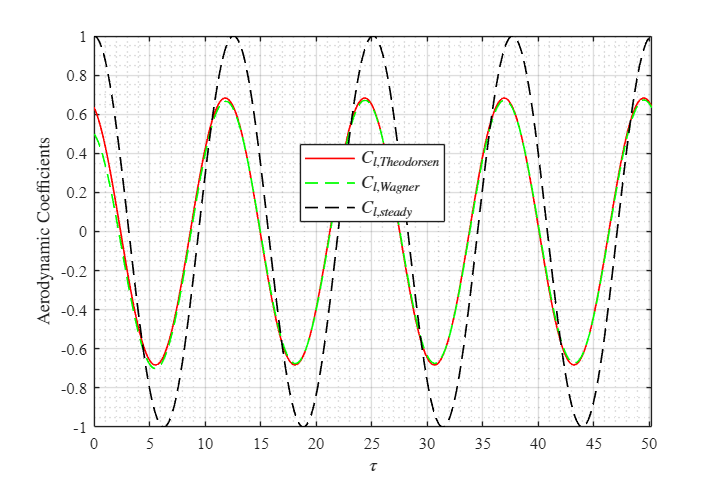

%% 2. WAGNER (Time Domain Solution - Convolution & Drag

sigma = 0; 
dtau = tau(2) - tau(1);

% Jones Approximation for Wagner Indicial Function

psi1 = 0.165; psi2 = 0.335;
eps1 = 0.0445; eps2 = 0.3;
phi_wagner = 1 - 0.165*exp(-0.0455*tau) - 0.335*exp(-0.3*tau);

alpha_t = alpha * exp(sigma*tau) .* cos(k*tau);
h_t     = h     * exp(sigma*tau) .* cos(k*tau - LAG);

alpha_dot_t = gradient(alpha_t, dtau);
h_dot_t     = gradient(h_t, dtau);

alpha_ddot_t = gradient(alpha_dot_t, dtau);
h_ddot_t     = gradient(h_dot_t, dtau);

Cl_nc = 2*pi * (h_ddot_t + alpha_dot_t - a*alpha_ddot_t);
Cm_nc = 2*pi * ( a*h_ddot_t - (0.5-a)*alpha_dot_t - (1/8+a^2)*alpha_ddot_t );

w_34 = h_dot_t + alpha_t + (0.5 - a)*alpha_dot_t;
dw_34 = h_ddot_t + alpha_dot_t + (0.5 - a)*alpha_ddot_t;

% Initialize Arrays
Cl_circ = zeros(1, length(tau));
Cs_wagner = zeros(1, length(tau)); % Leading Edge Suction
Q_eff_hist = zeros(1, length(tau)); % Effective downwash history

for i = 1:length(tau)
    t_curr = tau(i);
    
    if i == 1
        integral_val = 0;
    else
        % Convolution Integral: int_0^t [ dw/dsigma * phi(t - sigma) ] dsigma
        taus_int = tau(1:i);
        dw_hist = dw_34(1:i);
        % Kernel evaluation
        phi_kernel = 1 - 0.165*exp(-0.0455*(t_curr - taus_int)) - 0.335*exp(-0.3*(t_curr - taus_int));
        % Trapezoidal integration
        integral_val = trapz(taus_int, dw_hist .* phi_kernel);
    end
    
    % Effective Circulatory Downwash (Q_eff)
    % Q_eff = Integral + Initial_Transients
    Q_eff = integral_val + w_34(1) * phi_wagner(i);
    Q_eff_hist(i) = Q_eff;
    
    % Circulatory Lift: 4*pi * Q_eff (Matches slope 4pi)
    Cl_circ(i) = 4*pi * Q_eff;
    
    % --- DRAG / SUCTION CALCULATION ---
    % Suction Parameter S(t) = 2*Q_eff - alpha_dot
    S_t = 2 * Q_eff - alpha_dot_t(i);
    
    % Suction Force Coefficient Cs = pi * S^2
    Cs_wagner(i) = pi * (S_t)^2;
end

% Moment Circulatory Transfer
Cm_circ = Cl_circ * (0.5 + a); 

% --- C) Total Wagner Forces ---
Cl_wagner_t = Cl_nc + Cl_circ;
Cm_wagner_t = Cm_nc + Cm_circ;

% --- D) Total Wagner Drag ---
% Cd = Cl * alpha - Cs
Cd_wagner_t = Cl_wagner_t .* alpha_t - Cs_wagner;

figure(1)
clf
plot(tau, Cl_unsteady_t/C_l_steady,'r','LineWidth',1);
hold on 
plot(tau, Cl_wagner_t/C_l_steady, 'g--', 'LineWidth', 1);
hold on
plot(tau, Cl_steady_t/C_l_steady,'black--','LineWidth',1);
hold on 
legend('$C_{l,Theodorsen}$','$C_{l,Wagner}$', '$C_{l,steady}$','Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')
set(gcf, 'Renderer', 'painters');

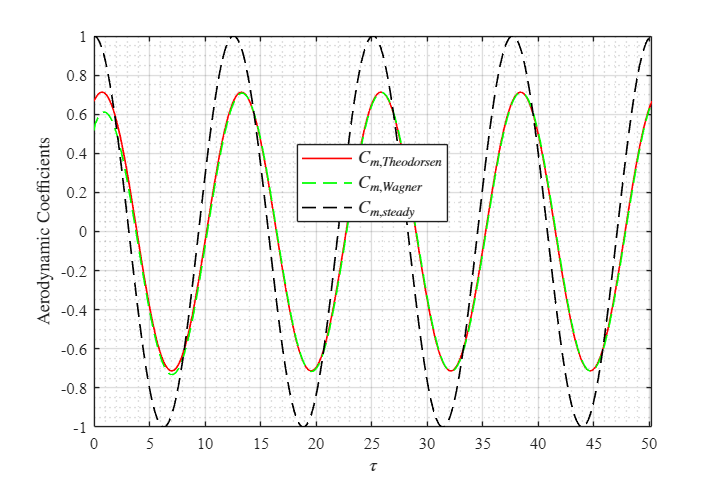


figure(2)
clf
plot(tau, Cm_unsteady_t/C_m_steady,'r','LineWidth',1);
hold on 
plot(tau, Cm_wagner_t/C_m_steady, 'g--', 'LineWidth', 1);
hold on
plot(tau, Cm_steady_t/C_m_steady,'black--','LineWidth',1);
hold on 
legend('$C_{m,Theodorsen}$', '$C_{m,Wagner}$','$C_{m,steady}$','Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')
set(gcf, 'Renderer', 'painters');

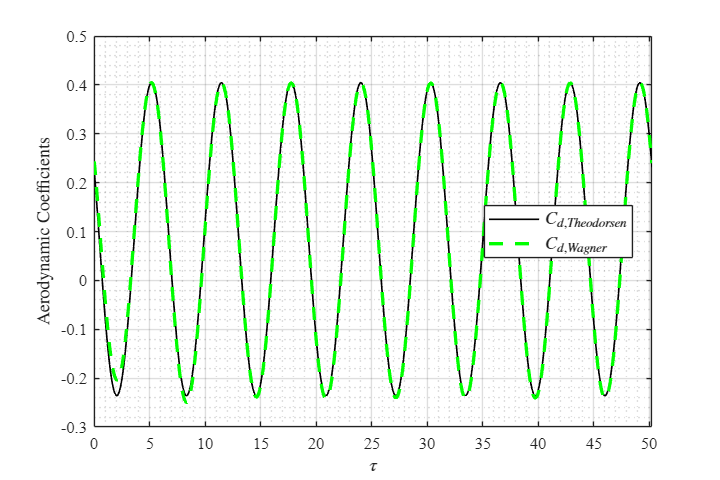


figure(4)
clf
plot(tau, Cd_t/C_l_steady,'black','LineWidth',1);
hold on
plot(tau, Cd_wagner_t/C_l_steady,'g--', 'LineWidth', 2);
legend('$C_{d,Theodorsen}$', '$C_{d,Wagner}$', 'Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')
set(gcf, 'Renderer', 'painters');

## Augmented Aerodynamic States

In the previous section, expressions for computing the unsteady lift, moment and drag in the time domain for an arbitrary motion of the airfoil were developed. These expressions are easy to compute when the motion of the airfoil is known, as the only mathematical issue is to solve the convolution integral, which should be an easy task.  However, in an aeroelastic system, the motion of the airfoil is an unknown. Hence, the unknowns are derived with respect to time and now they are also appear inside the convolution integral. This means that instead of having y typical ODE's system to solve, the equations of motion become an integro-differential system of equations. This kind of systems are extremely difficult to solve analytically, and numerical methods can also lead to difficult schemes in order to solve a system of equations of this type. 

In order to avoid having to cope with the convolution integral, there is a method called augmented aerodynamic states method (sometimes referred as lag states method in the literature). The main principle of this method, is to use the Laplace transform to substitute the convolution integral by a new ODE for a new system's state. It is important to point out, that this method works due to the numerical approximations of the Wagner's indicial function as a summation of exponential terms, as the one presented earlier (Jones approximation). 

A general form of this Wagner's functions approximations is:


$$\Phi (\tau) = 1 - \sum_{i = 1}^{n} \psi_i\cdot e^{-\epsilon_i \tau}$$


For Jones approximation, $n=2$ with: $\psi_1 = 0.165$, $\psi_2 = 0.335$, $\epsilon_1 = 0.455$, $\epsilon_2 = 0.3$.

The procedure is common to all the aerodynamic loads, as the convolution integral is exactly the same for all cases. The first step is to apply the Laplace transform to the convolution integral that appears in all the circulatory terms of the loads $I_c(\tau)$:


$$I_c(\tau)= \hat w_{3/4}(0)\Phi(\tau)+\int_0^\tau{\frac{d \hat w_{3/4}(\sigma)}{d\sigma}{\Phi(\tau-\sigma)}d\sigma} = I_{c1}(\tau) + I_{c2}(\tau)$$


The Laplace transform of the first term is:


$$I_{c1}(s) = \mathcal{L}\left\{I_{c1}(\tau)\right\} = \hat w_{3/4}(0) \Phi(s)$$


where $\Phi(s)$ is the Laplace transform of $\Phi(\tau)$, being $s$ the Laplace complex variable. For the second term, the Laplace transform can be computed making use of the convolution property as:


$$I_{c2}(s) = \mathcal{L}\left\{I_{c2}(\tau)\right\} = \Phi(s)\cdot \left[s\hat W_{3/4}(s) - \hat w_{3/4}(0) \right]$$


Adding both terms, leads to:


$$I_c(s) = I_{c1}(s) + I_{c2}(s) = s\Phi(s)\hat W_{3/4}(s)$$


Using the general expression of sum of exponential terms, the Laplace transform of the Wagner's indicial function can be expressed as:


$$\Phi(s) = \mathcal{L}\left\{\Phi(\tau)\right\} = \frac{1}{s} - \sum_{i =1}^{n}\frac{\psi_i}{s+\epsilon_i}$$


Substituting this expression in $I_c(s)$:


$$I_c(s) = s \hat W_{3/4}(s)\cdot \left(\frac{1}{s} - \sum_{i =1}^{n}\frac{\psi_i}{s+\epsilon_i} \right) =  \hat W_{3/4}(s)\cdot \left( 1 - \sum_{i =1}^{n}\frac{s \psi_i}{s+\epsilon_i} \right) $$


Each term from the summation can be reorganized as:


$$\frac{s \psi_i}{s+\epsilon_i} = \psi_i - \frac{\epsilon_i\psi_i}{s+\epsilon_i}$$


Hence,


$$I_c(s) =   \hat W_{3/4}(s)\cdot \left( 1 - \sum_{i =1}^{n}\psi_i + \sum_{i =1}^{n}\frac{\epsilon_i\psi_i}{s+\epsilon_i} \right) $$


This last equation contains all the information about the circulatory effect of the wake, but in the Laplace domain. The straightforward way to proceed now on, would be to directly apply the inverse Laplace transform to this last expression, in order to obtain the time domain wake effect. At this point, is where the augmented aerodynamic states are defined to facilitate the process of getting back to the time domain. This augmented aerodynamic states (also called lag states) are defined as follows:


$$X_i(s) = \frac{ \hat W_{3/4}(s) }{s+\epsilon_i}$$


This last equation, is the core of the augmented states method, as they conform the new ordinary differential equations that will substitute the convolution integral, but which contain the exact same information about the circulatory behavior of the system due to the wake effect. In order to get back to the time domain, the expression $I_c(s)$ can be now rearranged as a function of this new aerodynamic lag states in the Laplace domain:


$$I_c(s) =   \hat W_{3/4}(s)\cdot \left( 1 - \sum_{i =1}^{n}\psi_i \right) + \sum_{i =1}^{n}\epsilon_i \psi_iX_i(s)$$


As every $\psi_i$ and $\epsilon_i$ is a constant, the inverse Laplace transform of the last expression is easy and straightforward:


$$I_c(\tau) =   \hat w_{3/4}(\tau)\cdot \left( 1 - \sum_{i =1}^{n}\psi_i \right) + \sum_{i =1}^{n}\epsilon_i \psi_ix_i(\tau)$$


where $\mathcal{L}^{-1}\{X_i(s)\} = x_i(\tau)$, and $\mathcal{L}^{-1}\{\hat W_{3/4}(s)\} = \hat w_{3/4}(\tau)$.

Thus, this last expression allows to write down the aerodynamic loads in terms of these new augmented aerodynamic states, without needing to deal with the convolution integral. The expressions of the circulatory parts of the aerodynamic loads with this new formulation are:


$$C_l(\tau) = \underbrace{2\pi\left(\dot{\alpha} +\frac{\ddot{h}}{b} - a\ddot\alpha\right)}_{C_l^{NC}} + \underbrace{4\pi\left[\hat w_{3/4}(\tau) \Phi_0 + \sum_{i =1}^{n}\epsilon_i \psi_i x_i(\tau) \right]}_{C_l^{C}}$$



$$C_m(\tau) = \underbrace{-2\pi\left[\left(\frac{1}{2}-a\right)\dot{\alpha} + a\frac{\ddot{h}}{b} + \left(\frac{1}{8}+a^2\right)\ddot\alpha\right]}_{C_m^{NC}} + \underbrace{4\pi\left( \frac{1}{2}+a\right)\left[\hat w_{3/4}(\tau)\Phi_0 + \sum_{i =1}^{n}\epsilon_i \psi_i  x_i(\tau) \right]}_{C_m^{C}}$$



$$C_d(\tau) = \alpha C_l(\tau) - \pi \left\{2\left[ \hat w_{3/4}(\tau)\Phi_0 + \sum_{i =1}^{n}\epsilon_i \psi_i x_i(\tau) \right] - \dot \alpha \right\}^2$$


Note that $\left( 1 - \sum_{i =1}^{n}\psi_i \right) = \Phi(\tau = 0) = \Phi_0$.

The next step is to define the set of ordinary differential equations that determine the time evolution of the augmented states $x_i(\tau)$. In order to do so, the equation in the Laplace domain needs to be rearranged, and the inverse Laplace transform should be applied. 


$$sX_i(s) = \hat W_{3/4}(s) - \epsilon_iX_i(s)$$


And applying the inverse Laplace transform to this equation, the resulting ODE is:


$$\dot x_i(\tau) = \hat w_{3/4}(\tau)-\epsilon_ix_i(\tau)$$


with initial condition $x_i(0) = 0$.

Hence, if the motion of the airfoil is determined ($\hat w_{3/4}(\tau)$ is known), the augmented aerodynamic states can be integrated in time. Once these states are computed, the aerodynamic forces are also determined in the time domain. The advantage that this method presents, is to avoid having to solve the convolution integral. Thus, the aerodynamic loads can be fully computed for an arbitrary airfoil motion, by only needing to solve a simpler system of ordinary differential equations in time. 

Regarding the aeroelastic analysis, this method allows to write down the system evolution in a conventional state-space representation in the time domain. This is convenient for various reasons. The first one is that unlike frequency domain methods as k and pk, the evolution of the system in time domain can be studied, which means getting accurate information of the aeroelastic response of the system not only at the flutter point.

Secondly, this way of representing the system also allows to compute the aeroelastic response to arbitrary aerodynamic loads, instead of purely harmonic (as was the case of frequency domain method due to the limitations of Theodorsen's theory). 

Moreover, state-space representations can be slightly modified to cope with nonlinearities of the system, which was impossible to do with frequency domain methods. This is key when unsteady drag is to be included in the system aerodynamic loads contribution, as it is essentially non linear force. 

Other advantages that this kind of time representations of aeroelastic systems present, are further explained in the literature. For example, in order to develop a time controller, state-space representation is the most convenient way to write down a system's equations.

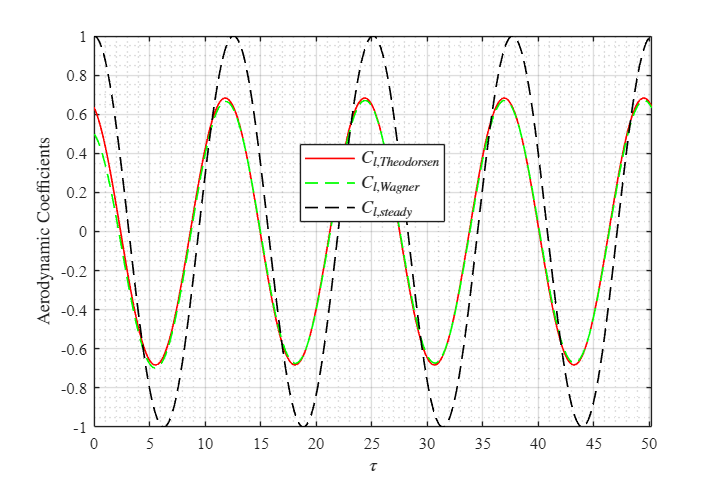

%% LAG STATES METHOD 

% Jones approximation to Wagner's function

psi1 = 0.165; psi2 = 0.335;
eps1 = 0.0445; eps2 = 0.3;
phi_wagner = 1 - 0.165*exp(-0.0455*tau) - 0.335*exp(-0.3*tau);

% Defining the aerodynamic augmented (or lag) states
x1 = zeros(length(tau),1);
x2 = zeros(length(tau),1);
dtau = tau(2) - tau(1);

% Down wash at 3/4 of the chord
w_34 = h_dot_t + alpha_t + (0.5-a)*alpha_dot_t;

for i = 1:(length(tau)-1)
    % Integration of the aerodynamic lag states differential equations in
    % the time domain
    x1(i+1) = x1(i) + dtau*(w_34(i) - eps1*x1(i)); 
    x2(i+1) = x2(i) + dtau*(w_34(i) - eps2*x2(i));

end

% Non circulatory terms (they don't depend on the lag states and Wagner function)
Cl_nc = 2*pi*(h_ddot_t + alpha_dot_t - a*alpha_ddot_t);
Cm_nc = -2*pi*(-a*h_ddot_t + (0.5-a)*alpha_dot_t + (1/8+a^2)*alpha_ddot_t);
Cs_nc = -alpha_dot_t;

Cl_c = zeros(length(tau),1);
Cm_c = zeros(length(tau),1);
Cs_c = zeros(length(tau),1);

for i = 1:length(tau)
    % Circulatory terms (they depend on the lag states and Wagner function)
    Cl_c(i) =  4*pi*(phi_wagner(1)*w_34(i) + eps1*psi1*x1(i) + eps2*psi2*x2(i));
    Cm_c(i) = (0.5+a)*Cl_c(i);
    Cs_c(i) =  2*(phi_wagner(1)*w_34(i) + eps1*psi1*x1(i) + eps2*psi2*x2(i));

end

Cl_lag_states_t = Cl_nc + Cl_c';
Cm_lag_states_t = Cm_nc + Cm_c';
Cs_lag_states_t = Cs_nc + Cs_c';
Cd_lag_states_t = zeros(length(tau),1);

for i = 1:length(tau)
    % Defining the unsteady drag from the LES and Lift contributions
    Cd_lag_states_t(i) = Cl_lag_states_t(i)*alpha_t(i) - pi*Cs_lag_states_t(i)^2;

end

figure(1)
clf
plot(tau, Cl_unsteady_t/C_l_steady,'r','LineWidth',1);
hold on 
plot(tau, Cl_lag_states_t/C_l_steady, 'g--', 'LineWidth', 1);
hold on
plot(tau, Cl_steady_t/C_l_steady,'black--','LineWidth',1);
hold on 
legend('$C_{l,Theodorsen}$','$C_{l,Wagner}$', '$C_{l,steady}$','Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')
set(gcf, 'Renderer', 'painters');

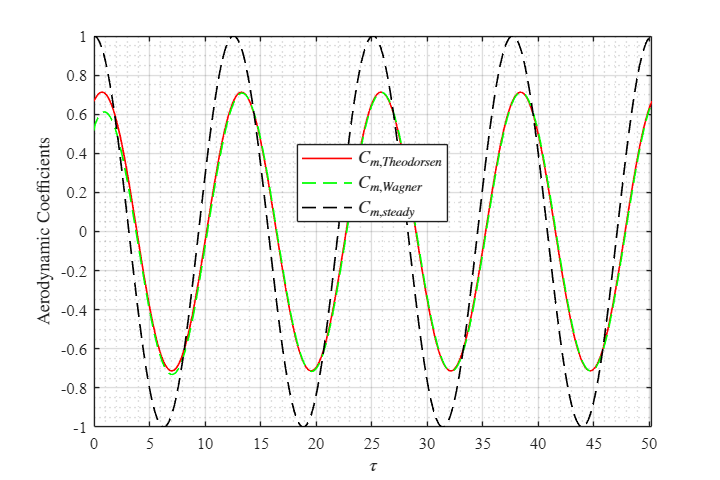


figure(2)
clf
plot(tau, Cm_unsteady_t/C_m_steady,'r','LineWidth',1);
hold on 
plot(tau, Cm_lag_states_t/C_m_steady, 'g--', 'LineWidth', 1);
hold on
plot(tau, Cm_steady_t/C_m_steady,'black--','LineWidth',1);
hold on 
legend('$C_{m,Theodorsen}$', '$C_{m,Wagner}$','$C_{m,steady}$','Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')
set(gcf, 'Renderer', 'painters');

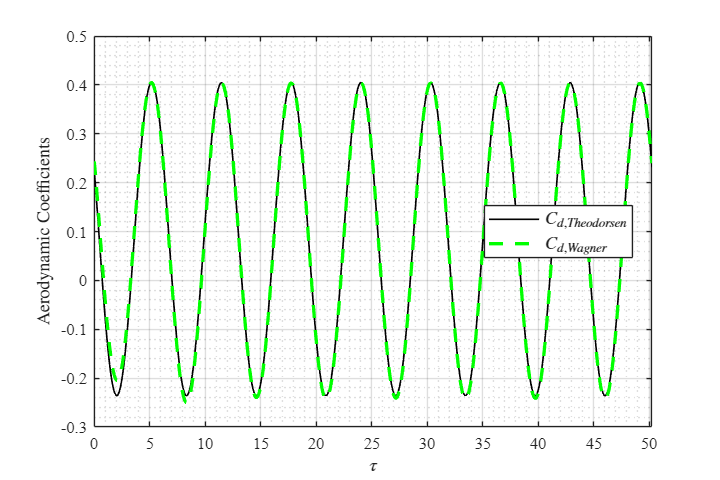


figure(4)
clf
plot(tau, Cd_t/C_l_steady,'black','LineWidth',1);
hold on
plot(tau, Cd_lag_states_t/C_l_steady,'g--', 'LineWidth', 2);
legend('$C_{d,Theodorsen}$', '$C_{d,Wagner}$', 'Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')
set(gcf, 'Renderer', 'painters');